# Sorting Cells automatically with k-means and discrete wavelet clustering

Takes all spikes on one wire and sorts them independently of original labels using k-means and wavelet clustering. 

Change Log:

Created by Brian Carson on 3/2018 for sorting of spikes from Q175 mice.

Preallocate memory and concatenate cells from one wire.

waves=[];
wire=3;
waves=cell2mat(waveforms(:,wire)); % gives n spikes by m points array
if(length(waves)>5000)
    waves=waves(rand(5000)>0.5);
end

wvs=waveforms(:,wire);
wvs=wvs(~cellfun('isempty',wvs));
sze=[];
labels=[];
for i=1:size(wvs,1)
    sze(i)=size(wvs{i},1);
    labels=[labels (ones(sze(i),1)*i)'];
end

Cluster each spike

waveletClusters = mdwtcluster(waves,'wname','db2');

Indices of clusters

Idx = waveletClusters.IdxCLU;

Plot each cluster in a subplot using cluster indices at the level 1 decomposition

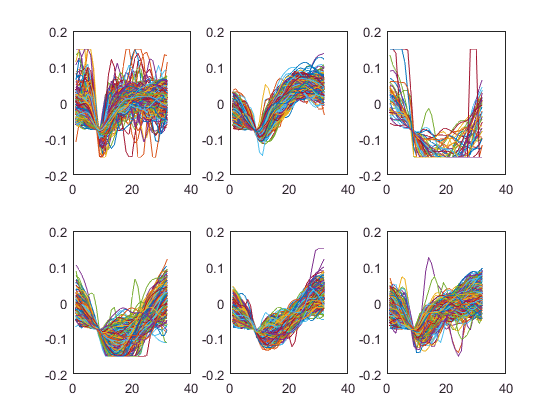

figure
for j=1:size(Idx,2)
    subplot(2,3,j)
    plot(waves(Idx(:,1)==j,:)')
end

 k-means clustering using amount of wavelet clusters for cluster cutoff parameter

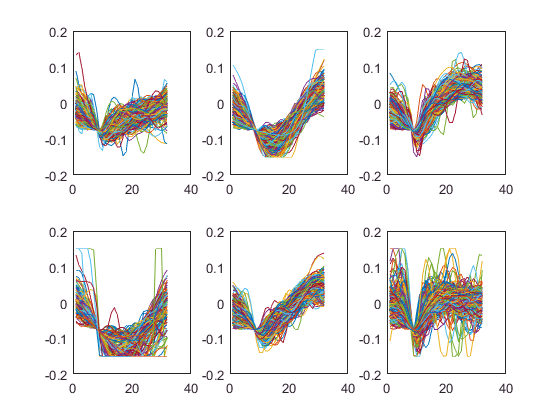

kmClusters=kmeans(waves,size(Idx,2));
figure
for j=1:size(Idx,2)
    subplot(2,3,j)
    plot(waves(kmClusters==j,:)')
end

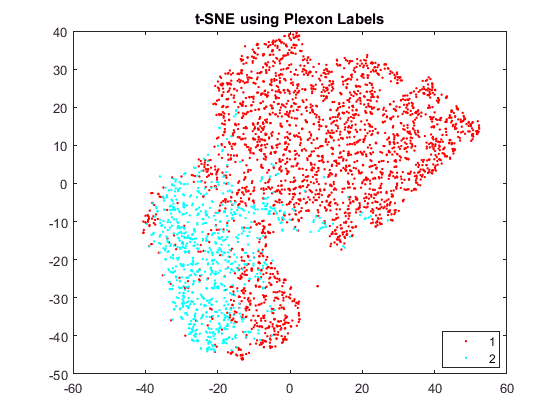


y=tsne(waves);
figure
gscatter(y(:,1),y(:,2),labels)
title('t-SNE using Plexon Labels')

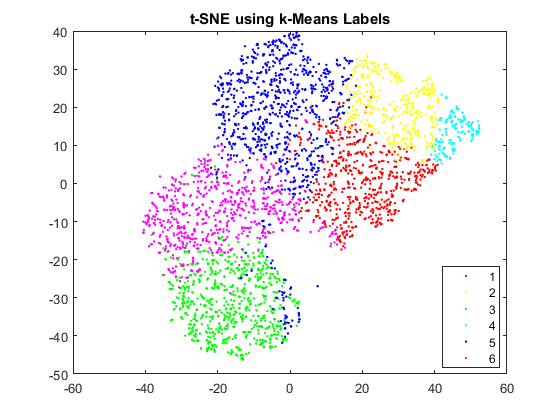

figure
gscatter(y(:,1),y(:,2),kmClusters)
title('t-SNE using k-Means Labels')

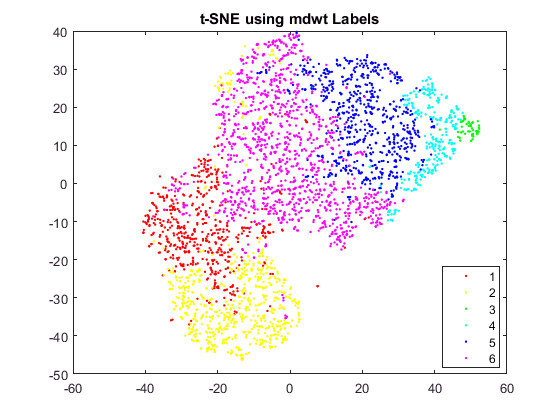

figure
gscatter(y(:,1),y(:,2),Idx(:,1))
title('t-SNE using mdwt Labels')